clear

f = 3;
uJ = 0.5;
m = 2.5;
beta = 0.0;
a = 0; %1;
mI = m;
uA = 0.5;
mb = 0.2;
mbI = mb;

S = load('DATA_THEE_FIG2_C')

S = struct with fields:
            A: [404×1 double]
    AveN_hold: [404×1 double]
          J_I: [404×1 double]
          J_S: [404×1 double]
          Tot: [404×1 double]
    beta_hold: [404×1 double]
     beta_min: 0.1221


S1 = load('DATA_THEE_FIG2_C1')

S1 = struct with fields:
               A: [404×1 double]
       AveA_hold: [404×1 double]
      AveJI_hold: [404×1 double]
      AveJS_hold: [404×1 double]
    AveJsum_hold: [404×1 double]
       AveN_hold: [404×1 double]
             J_I: [404×1 double]
             J_S: [404×1 double]
           J_sum: [404×1 double]
             Tot: [404×1 double]
       beta_hold: [404×1 double]
        beta_min: 0.1221


%S2 = load('DATA_THEE_FIG2_C_2')
S2 = load('DATA_THEE_FIG2_C2')

S2 = struct with fields:
               A: [404×1 double]
       AveA_hold: [404×1 double]
      AveJI_hold: [404×1 double]
      AveJS_hold: [404×1 double]
    AveJsum_hold: [404×1 double]
       AveN_hold: [404×1 double]
             J_I: [404×1 double]
             J_S: [404×1 double]
           J_sum: [404×1 double]
             Tot: [404×1 double]
       beta_hold: [404×1 double]
        beta_min: 0.0472


S3 = load('DATA_THEE_FIG2_C_tau')

S3 = struct with fields:
    beta_hold2: [312×1 double]
      tau_hold: [312×1 double]


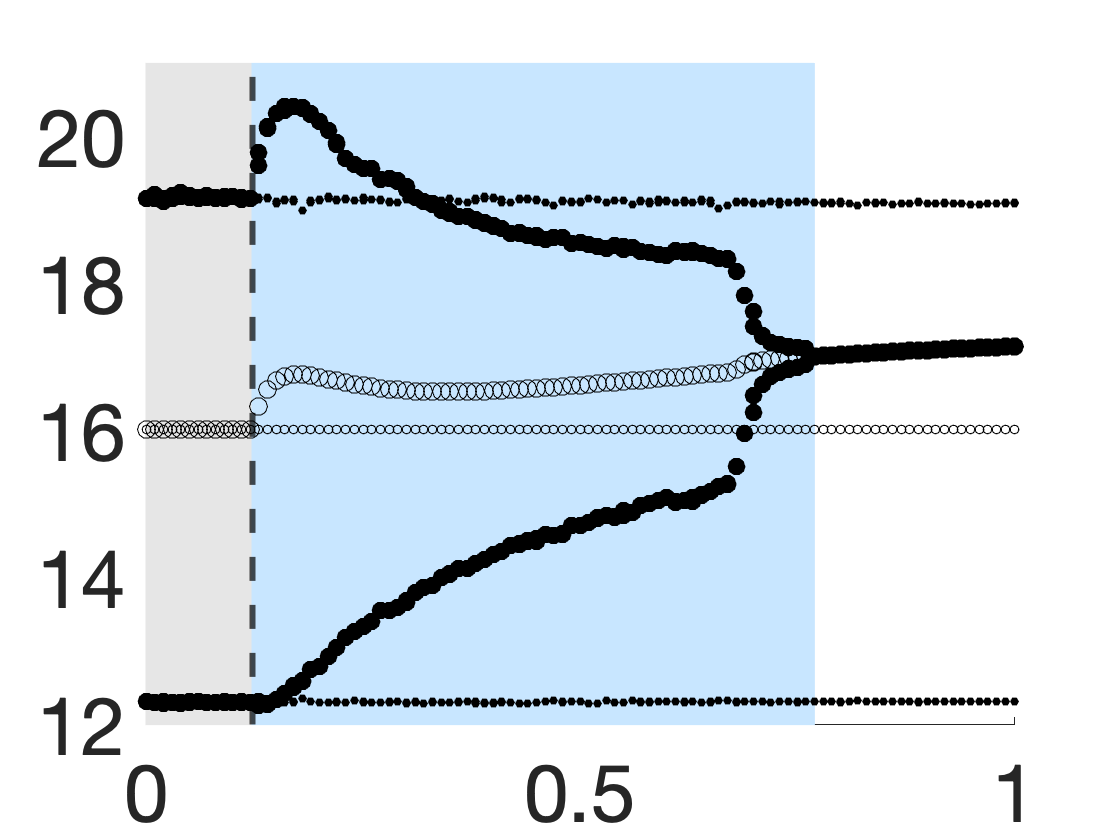



beta_bound = min(S1.beta_hold(round(S1.AveN_hold,3)==round(S1.Tot,3)));

% % %% Calculate Juvenile Bmin
% %  N = ones(2,1);
% %  T_interval = [0, 1000];
% %  Init_conditions = [2; 2].*N;
% % [T, N] = ode45(@(t,N)  two_stage_growth(t,N,f,m,mb,uJ,uA), T_interval, Init_conditions);
% % 
% %     options = odeset('MaxStep',1e-4);
% %     T_interval = [0, 20];
% %     Init_conditions = N(end,:)';
% %     N = ones(2,1);
% %     [T, N] = ode45(@(t,N)  two_stage_growth(t,N,f,m,mb,uJ,uA), T_interval, Init_conditions,options);
% % 
% %     [pks,locs] = findpeaks(N(:,1));
% %     AveJ = sum(N(locs(end-1):locs(end),1))/(length(locs(end-1):locs(end)));
% % 
% %     beta_min = (sum(max(mI-mbI*(N(locs(end-1):locs(end),1)),0))/(length(locs(end-1):locs(end))) + (uJ+a))/AveJ
% %     beta_min2 = [(mI+uJ+a)/AveJ - mbI]
% %     
% % 
% % 
% %  N = ones(3,1); % Make vector to hold densities
% %     T_interval = [0, 1000];
% %     Init_conditions = [9; 0.1; 3].*N;
% %     %Init_conditions = [2.5; 6.7; 3.2].*N;
% %     
% % [T, N] = ode45(@(t,N)  pathogen_attacks_J_wMat_mb(t,N,f,uJ,m,beta,a,mI,uA,mb,mbI), T_interval, Init_conditions);
% % 
% % hold_mat = N((end-1000):end,:);
% % JperA_series = (hold_mat(:,1)+hold_mat(:,2))./hold_mat(:,3);
% % JperA = [min(JperA_series); max(JperA_series)];
% % J_S = [min(hold_mat(:,1)); max(hold_mat(:,1))];
% % J_I = [min(hold_mat(:,2)); max(hold_mat(:,2))];
% % A = [min(hold_mat(:,3)); max(hold_mat(:,3))];
% % Tot = [min((hold_mat(:,1)+hold_mat(:,2)+hold_mat(:,3))); max((hold_mat(:,1)+hold_mat(:,2)+hold_mat(:,3)))];
% % 
% %     T_interval2 = [0, 20];
% %     Init_conditions2 = N(end,:)';
% %     N2 = ones(3,1);
% %     [T, N2] = ode45(@(t,N2)  pathogen_attacks_J_wMat_mb(t,N2,f,uJ,m,beta,a,mI,uA,mb,mbI), T_interval2, Init_conditions2,options);
% %     TotalN = N2(:,1) + N2(:,2) + N2(:,3);
% %     [pks,locs] = findpeaks(TotalN(:,1));
% %     AveN = sum(TotalN(locs(end-1):locs(end),1))/(length(locs(end-1):locs(end)));
% %     AveN_hold = AveN*ones(2,1);
% % 
% % beta_hold = beta*ones(2,1);
% % beta_vec = 0.0:0.01:1;
% % %beta_vec = 0.0:0.001:0.6;
% % %%Loop through a range of beta
% % for i = 2:length(beta_vec)
% %     beta = beta_vec(i);
% %  N = ones(3,1); % Make vector to hold densities
% %     Init_conditions = hold_mat(end,:) + [0, 0.1, 0];
% %     %JS_star = (a + uJ)/beta;
% %     %JI_star = (-a*f*mb + beta*f*m + a*mb*uA - beta*m*uA - f*mb*uJ - beta*uA*uJ + mb*uA*uJ)/(beta*(f*mb + beta*uA - mb*uA));
% %     %A_star = -(a*mb - beta*m)*(a + uJ)/(beta*(f*mb + beta*uA - mb*uA));
% %     %Init_conditions = [JS_star; JI_star; A_star] + [0, 0.1, 0];
% %     
% %     [T, N] = ode45(@(t,N)  pathogen_attacks_J_wMat_mb(t,N,f,uJ,m,beta,a,mI,uA,mb,mbI), T_interval, Init_conditions);
% % 
% % %%Find max and min of last 100 elements for each state variable
% %     hold_mat = N((end-1000):end,:);
% %     JperA_series = (hold_mat(:,1)+hold_mat(:,2))./hold_mat(:,3);
% %     JperA = [JperA; min(JperA_series); max(JperA_series)];
% %     J_S = [J_S; min(hold_mat(:,1)); max(hold_mat(:,1))];
% %     J_I = [J_I; min(hold_mat(:,2)); max(hold_mat(:,2))];
% %     A = [A; min(hold_mat(:,3)); max(hold_mat(:,3))];
% %     Tot = [Tot; min((hold_mat(:,1)+hold_mat(:,2)+hold_mat(:,3))); max((hold_mat(:,1)+hold_mat(:,2)+hold_mat(:,3)))];
% %     beta_hold = [beta_hold; beta_vec(i)*ones(2,1)];
% %     
% % T_interval2 = [0, 20];
% %     Init_conditions2 = N(end,:)';
% %     N2 = ones(3,1);
% %     [T, N2] = ode45(@(t,N2)  pathogen_attacks_J_wMat_mb(t,N2,f,uJ,m,beta,a,mI,uA,mb,mbI), T_interval2, Init_conditions2,options);
% %     TotalN = N2(:,1) + N2(:,2) + N2(:,3);
% %     [pks,locs] = findpeaks(TotalN(:,1));
% %     AveN = sum(TotalN(locs(end-1):locs(end),1))/(length(locs(end-1):locs(end)));
% %     AveN_hold = [AveN_hold; AveN*ones(2,1)];
% % end
% % 
% % for i = length(beta_vec):-1:1
% %     beta = beta_vec(i);
% %  N = ones(3,1); % Make vector to hold densities
% %     Init_conditions = hold_mat(end,:) + [0, -0.1, 0];
% %     
% %     [T, N] = ode45(@(t,N)  pathogen_attacks_J_wMat_mb(t,N,f,uJ,m,beta,a,mI,uA,mb,mbI), T_interval, Init_conditions);
% % 
% % %%Find max and min of last 100 elements for each state variable
% %     hold_mat = N((end-1000):end,:);
% %     JperA_series = (hold_mat(:,1)+hold_mat(:,2))./hold_mat(:,3);
% %     JperA = [JperA; min(JperA_series); max(JperA_series)];
% %     J_S = [J_S; min(hold_mat(:,1)); max(hold_mat(:,1))];
% %     J_I = [J_I; min(hold_mat(:,2)); max(hold_mat(:,2))];
% %     A = [A; min(hold_mat(:,3)); max(hold_mat(:,3))];    
% %     Tot = [Tot; min((hold_mat(:,1)+hold_mat(:,2)+hold_mat(:,3))); max((hold_mat(:,1)+hold_mat(:,2)+hold_mat(:,3)))];
% %     beta_hold = [beta_hold; beta_vec(i)*ones(2,1)];
% %     
% %     
% %     T_interval2 = [0, 20];
% %     Init_conditions2 = N(end,:)';
% %     N2 = ones(3,1);
% %     [T, N2] = ode45(@(t,N2)  pathogen_attacks_J_wMat_mb(t,N2,f,uJ,m,beta,a,mI,uA,mb,mbI), T_interval2, Init_conditions2,options);
% %     TotalN = N2(:,1) + N2(:,2) + N2(:,3);
% %     [pks,locs] = findpeaks(TotalN(:,1));
% %     AveN = sum(TotalN(locs(end-1):locs(end),1))/(length(locs(end-1):locs(end)));
% %     AveN_hold = [AveN_hold; AveN*ones(2,1)];
% % end

%%save('DATA_THEE_FIG2_C_2', 'beta_hold', 'Tot', 'beta_min', 'AveN_hold', 'A', 'J_I', 'J_S')


E = S2.beta_hold > S1.beta_min;
colors = get(gca,'ColorOrder');

figure
hold on
rectangle('Position',[0 0 S.beta_min 29],'FaceColor',[0.9 0.9 0.9],'EdgeColor',[0.9 0.9 0.9]); % Plots the rectangle
rectangle('Position',[S.beta_min 0 beta_bound-S.beta_min 29],'FaceColor',[200/255 230/255 255/255],'EdgeColor',[200/255 230/255 255/255]); % Plots the rectangle
%yline(S.Tot(1),'--','LineWidth',3,'Color',"black")%colors(1,:))
%yline(S.Tot(2),'--','LineWidth',3,'Color',"black")%colors(1,:))
%yline(S.AveN_hold(1),'--','LineWidth',3,'Color',"black")%colors(1,:))
%xline(S.beta_min,'--k','LineWidth',3)
xline(S.beta_min,'--k','LineWidth',3)
scatter(S.beta_hold, S.Tot, 80,"Filled","black")
scatter(S.beta_hold, S.AveN_hold, 80, "black")
scatter(S2.beta_hold, S2.Tot, 20,"Filled","black")
scatter(S2.beta_hold, S2.AveN_hold, 20, "black")
%scatter(S.beta_hold(S.beta_hold<round(S.beta_min,2)), S.Tot(S.beta_hold<round(S.beta_min,2)),80,[0.3010 0.7450 0.9330],"Filled")
%ylabel("Total")
ylim([12 21])
set(gca, 'FontSize', 40)
%xlabel("Transmission rate, \beta_J", "FontSize", 36)
hold off

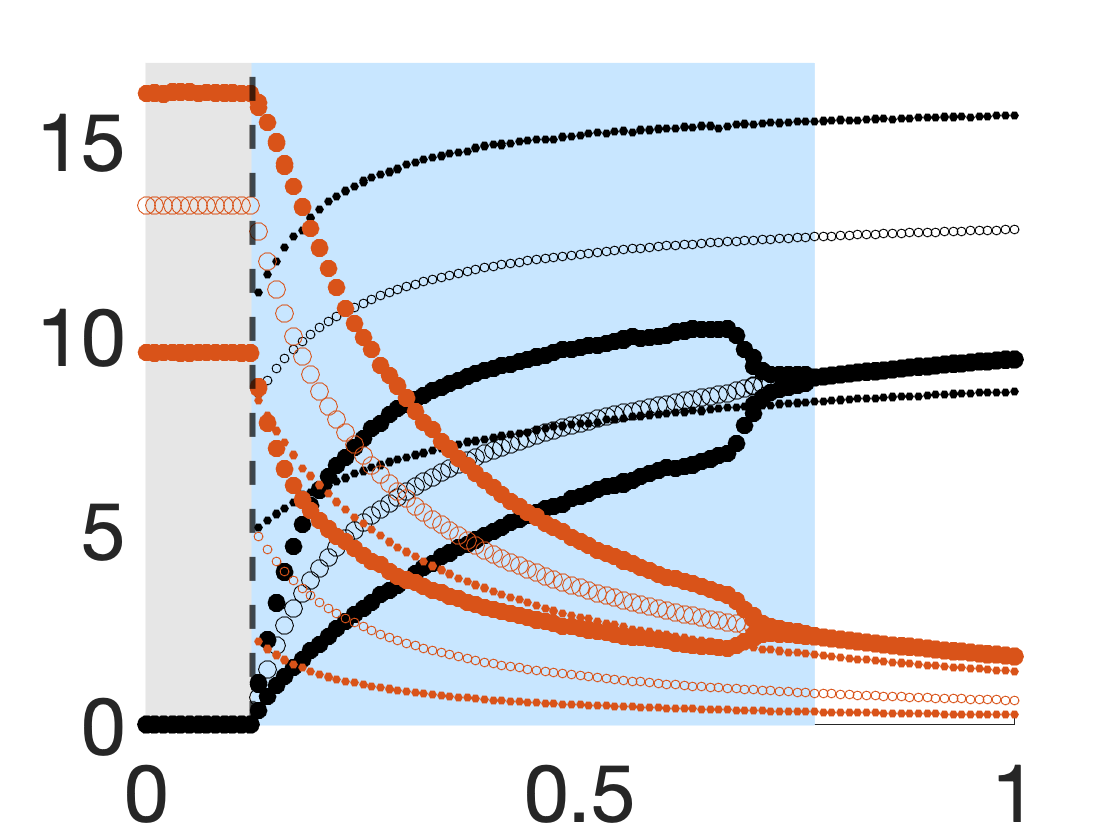


figure 
rectangle('Position',[0 0 S.beta_min 29],'FaceColor',[0.9 0.9 0.9],'EdgeColor',[0.9 0.9 0.9]); % Plots the rectangle
rectangle('Position',[S.beta_min 0 beta_bound-S.beta_min 29],'FaceColor',[200/255 230/255 255/255],'EdgeColor',[200/255 230/255 255/255]); % Plots the rectangle
hold on
%rectangle('Position',[0 0 S1.beta_min 29],'FaceColor',[0.6 0.6 0.6],'EdgeColor',[0.8 0.8 0.8]); % Plots the rectangle
%rectangle('Position',[0.12 0 0.19 29],'FaceColor',[0.6 0.6 0.6],'EdgeColor',[0.6 0.6 0.6]); % Plots the rectangle
xline(S1.beta_min,'--k','LineWidth',3)
scatter(S1.beta_hold, S1.J_I, 80, "k", "Filled")
scatter(S1.beta_hold, S1.AveJI_hold, 80, "k")
scatter(S2.beta_hold(E), S2.J_I(E), 20, "k", "filled")
scatter(S2.beta_hold(E), S2.AveJI_hold(E), 20, "k")
scatter(S1.beta_hold, S1.J_S, 80, colors(2,:), "Filled")
scatter(S1.beta_hold, S1.AveJS_hold, 80, colors(2,:))
scatter(S2.beta_hold(E), S2.J_S(E), 20, colors(2,:), "filled")
scatter(S2.beta_hold(E), S2.AveJS_hold(E), 20, colors(2,:))
%ylabel("J       ")
ylim([0 17])
set(gca, 'FontSize', 40)
%yyaxis right
%ylabel("Total J")
%scatter(S1.beta_hold, S1.J_S+S1.J_I, 80, "filled")
%scatter(S2.beta_hold, S2.J_S+S2.J_I, 80)
%ylabel("Incidence")
%scatter(S1.beta_hold, S1.J_I./(S1.J_S+S1.J_I), 80, "filled")
%ylim([0 1])
%xline(4,'--r',{'Beta','=0.2'})
%xline(0.05,'--r','LineWidth',2)
%xline(0.12,'--r','LineWidth',2)
%xline(0.16,'--r','LineWidth',2)
%xline(0.35,'--r','LineWidth',2)
%hYLabel = get(gca,'YLabel');
%set(hYLabel,'rotation',0,'VerticalAlignment','middle')
%xlabel("Transmission rate, \beta", "FontSize", 36)
hold off

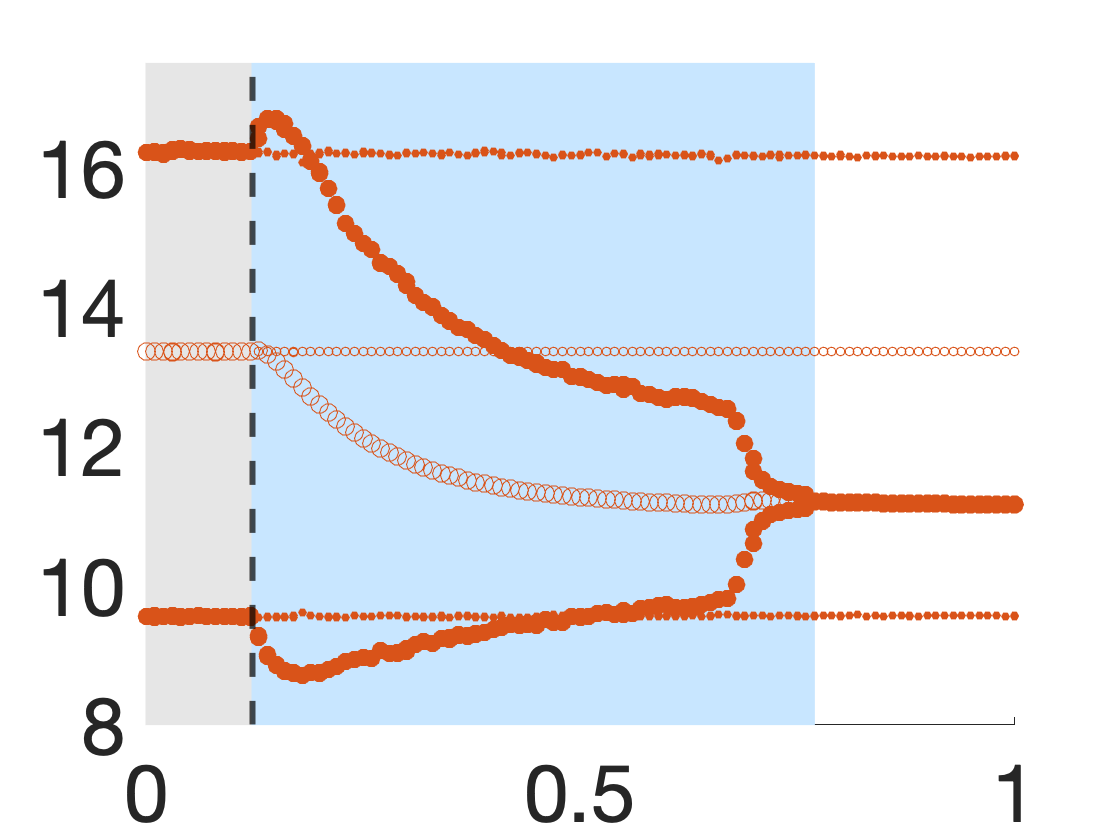


figure 
rectangle('Position',[0 0 S.beta_min 29],'FaceColor',[0.9 0.9 0.9],'EdgeColor',[0.9 0.9 0.9]); % Plots the rectangle
rectangle('Position',[S.beta_min 0 beta_bound-S.beta_min 29],'FaceColor',[200/255 230/255 255/255],'EdgeColor',[200/255 230/255 255/255]); % Plots the rectangle
hold on
xline(S1.beta_min,'--k','LineWidth',3)
scatter(S1.beta_hold, S1.J_sum, 80, colors(2,:), "filled")
scatter(S1.beta_hold, S1.AveJsum_hold, 80, colors(2,:))
scatter(S2.beta_hold(E), S2.J_sum(E), 20, colors(2,:), "filled")
scatter(S2.beta_hold(E), S2.AveJsum_hold(E), 20, colors(2,:))
%ylabel("J       ")
ylim([8 17.5])
set(gca, 'FontSize', 40)
hold off

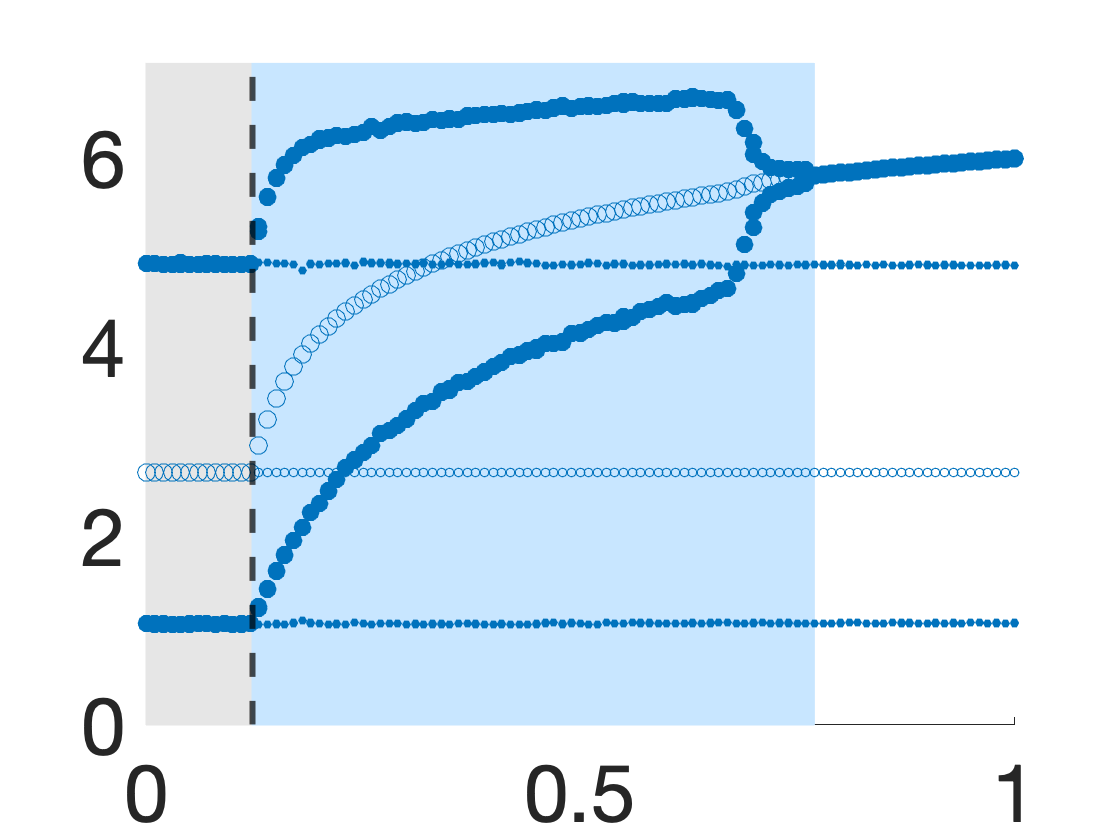


% % figure 
% % rectangle('Position',[0 0 S.beta_min 29],'FaceColor',[0.9 0.9 0.9],'EdgeColor',[0.9 0.9 0.9]); % Plots the rectangle
% % rectangle('Position',[S.beta_min 0 beta_bound-S.beta_min 29],'FaceColor',[200/255 230/255 255/255],'EdgeColor',[200/255 230/255 255/255]); % Plots the rectangle
% % hold on
% % %rectangle('Position',[0 0 S1.beta_min 29],'FaceColor',[0.6 0.6 0.6],'EdgeColor',[0.8 0.8 0.8]); % Plots the rectangle
% % %rectangle('Position',[0.12 0 0.19 29],'FaceColor',[0.6 0.6 0.6],'EdgeColor',[0.6 0.6 0.6]); % Plots the rectangle
% % xline(S1.beta_min,'--k','LineWidth',3)
% % scatter(S1.beta_hold, S1.J_S, 80, colors(2,:), "Filled")
% % scatter(S1.beta_hold, S1.AveJS_hold, 80, colors(2,:))
% % %scatter(S2.beta_hold(E), S2.J_S(E), 40, colors(2,:))
% % %scatter(S2.beta_hold(E), S2.J_I(E), 40, "k")
% % scatter(S2.beta_hold(E), S2.J_S(E), 20, colors(2,:), "filled")
% % scatter(S2.beta_hold(E), S2.AveJS_hold(E), 20, colors(2,:))
% % %ylabel("J       ")
% % ylim([0 18])
% % set(gca, 'FontSize', 40)
% % %yyaxis right
% % %ylabel("Total J")
% % %scatter(S1.beta_hold, S1.J_S+S1.J_I, 80, "filled")
% % %scatter(S2.beta_hold, S2.J_S+S2.J_I, 80)
% % %ylabel("Incidence")
% % %scatter(S1.beta_hold, S1.J_I./(S1.J_S+S1.J_I), 80, "filled")
% % %ylim([0 1])
% % %xline(4,'--r',{'Beta','=0.2'})
% % %xline(0.05,'--r','LineWidth',2)
% % %xline(0.12,'--r','LineWidth',2)
% % %xline(0.16,'--r','LineWidth',2)
% % %xline(0.35,'--r','LineWidth',2)
% % %hYLabel = get(gca,'YLabel');
% % %set(hYLabel,'rotation',0,'VerticalAlignment','middle')
% % %xlabel("Transmission rate, \beta", "FontSize", 36)
% % hold off

% 
% 
% figure
% hold on
% rectangle('Position',[0 0 S.beta_min 29],'FaceColor',[0.8 0.8 0.8],'EdgeColor',[0.8 0.8 0.8]); % Plots the rectangle
% %rectangle('Position',[0.12 0 0.19 29],'FaceColor',[0.6 0.6 0.6],'EdgeColor',[0.6 0.6 0.6]); % Plots the rectangle
% xline(S.beta_min,'--k','LineWidth',2)
% scatter(S.beta_hold, S.J_I, 80, "Filled")
% ylabel("J_I       ")
% ylim([0 18])
% set(gca, 'FontSize', 40)
% %xline(4,'--r',{'Beta','=0.2'})
% %xline(0.05,'--r','LineWidth',2)
% %xline(0.12,'--r','LineWidth',2)
% %xline(0.16,'--r','LineWidth',2)
% %xline(0.35,'--r','LineWidth',2)
% hYLabel = get(gca,'YLabel');
% %set(hYLabel,'rotation',0,'VerticalAlignment','middle')
% %xlabel("Transmission rate, \beta", "FontSize", 36)
% hold off


figure
hold on
rectangle('Position',[0 0 S.beta_min 29],'FaceColor',[0.9 0.9 0.9],'EdgeColor',[0.9 0.9 0.9]); % Plots the rectangle
rectangle('Position',[S.beta_min 0 beta_bound-S.beta_min 29],'FaceColor',[200/255 230/255 255/255],'EdgeColor',[200/255 230/255 255/255]); % Plots the rectangle
xline(S1.beta_min,'--k','LineWidth',3)
scatter(S1.beta_hold, S1.A, 80, "Filled")
scatter(S1.beta_hold, S1.AveA_hold, 80, colors(1,:))
%scatter(S2.beta_hold(E), S2.A(E), 40, colors(1,:))
scatter(S2.beta_hold(E), S2.A(E), 20, colors(1,:), "filled")
scatter(S2.beta_hold(E), S2.AveA_hold(E), 20, colors(1,:))
%ylabel("A_S       ")
ylim([0 7])
set(gca, 'FontSize', 40)
%xline(4,'--r',{'Beta','=0.2'})
%xline(0.05,'--r','LineWidth',2)
%xline(0.12,'--r','LineWidth',2)
%xline(0.16,'--r','LineWidth',2)
%xline(0.35,'--r','LineWidth',2)
hYLabel = get(gca,'YLabel');
%set(hYLabel,'rotation',0,'VerticalAlignment','middle')
%xlabel("Transmission rate, \beta", "FontSize", 36)
hold off





% % figure
% % hold on
% % rectangle('Position',[0 0 S.beta_min 29],'FaceColor',[0.8 0.8 0.8],'EdgeColor',[0.8 0.8 0.8]); % Plots the rectangle
% % %rectangle('Position',[0.12 0 0.19 29],'FaceColor',[0.6 0.6 0.6],'EdgeColor',[0.6 0.6 0.6]); % Plots the rectangle
% % yline(S.Tot(1),'--','LineWidth',3,'Color',[0.3010 0.7450 0.9330])
% % yline(S.Tot(2),'--','LineWidth',3,'Color',[0.3010 0.7450 0.9330])
% % yline(S.AveN_hold(1),'--','LineWidth',3,'Color',[0.3010 0.7450 0.9330])
% % xline(S.beta_min,'--k','LineWidth',2)
% % scatter(S.beta_hold, S.Tot, 80,"Filled","black")
% % scatter(S.beta_hold, S.AveN_hold, 80, "black")
% % scatter(S.beta_hold(S.beta_hold<round(S.beta_min,2)), S.Tot(S.beta_hold<round(S.beta_min,2)),80,[0.3010 0.7450 0.9330],"Filled")
% % ylabel("Total")
% % ylim([10 21])
% % set(gca, 'FontSize', 40)
% % %xlabel("Transmission rate, \beta_J", "FontSize", 36)
% % hold off
% 
% figure
% hold on
% rectangle('Position',[0 0 S1.beta_min 29],'FaceColor',[0.8 0.8 0.8],'EdgeColor',[0.8 0.8 0.8]); % Plots the rectangle
% scatter(S1.beta_hold, (S1.J_S+S1.J_I)./(S1.J_S+S1.J_I+S1.A), 80, "filled")
% xline(S1.beta_min,'--k','LineWidth',2)
% ylabel("Proportion")
% %ylabel("J per total")
% ylim([0 1])
% %yyaxis right
% %ylabel("Incidence")
% scatter(S1.beta_hold, S1.J_I./(S1.J_S+S1.J_I), 80, "filled")
% %ylim([0 1])
% set(gca, 'FontSize', 40)
% %xline(4,'--r',{'Beta','=0.2'})
% %xline(0.05,'--r','LineWidth',2)
% %xline(0.12,'--r','LineWidth',2)
% %xline(0.16,'--r','LineWidth',2)
% %xline(0.35,'--r','LineWidth',2)
% %hYLabel = get(gca,'YLabel');
% %set(hYLabel,'rotation',0,'VerticalAlignment','middle')
% xlabel("Transmission rate, \beta_J", "FontSize", 36)
% %legend("J:A prop.", "AI prop.", "Location","southeast")
% hold off


% % 
% % figure
% % hold on
% % rectangle('Position',[0 0 S1.beta_min 29],'FaceColor',[0.9 0.9 0.9],'EdgeColor',[0.9 0.9 0.9]); % Plots the rectangle
% % rectangle('Position',[S1.beta_min 0 beta_bound-S1.beta_min 29],'FaceColor',[200/255 230/255 255/255],'EdgeColor',[200/255 230/255 255/255]); % Plots the rectangle
% % %scatter(S1.beta_hold, (S1.J_S+S1.J_I)./S1.A, "filled")
% % %ylabel("Incidence")
% % scatter(S1.beta_hold, S1.J_I./(S1.J_S+S1.J_I), 60, "filled")
% % %scatter(S2.beta_hold, S2.J_I./(S2.J_S+S2.J_I), "filled")
% % ylim([0 1])
% % set(gca, 'FontSize', 40)
% % xline(S1.beta_min,'--k','LineWidth',3)
% % %xline(4,'--r',{'Beta','=0.2'})
% % %xline(0.05,'--r','LineWidth',2)
% % %xline(0.12,'--r','LineWidth',2)
% % %xline(0.16,'--r','LineWidth',2)
% % %xline(0.35,'--r','LineWidth',2)
% % %hYLabel = get(gca,'YLabel');
% % %set(hYLabel,'rotation',0,'VerticalAlignment','middle')
% % %xlabel("Transmission rate", "FontSize", 36)
% % %legend("Hydra", "Null", "Location","southeast")
% % hold off
% % 
% % 
% % figure
% % rectangle('Position',[0 0 S1.beta_min 29],'FaceColor',[0.9 0.9 0.9],'EdgeColor',[0.9 0.9 0.9]); % Plots the rectangle
% % rectangle('Position',[S1.beta_min 0 beta_bound-S1.beta_min 29],'FaceColor',[200/255 230/255 255/255],'EdgeColor',[200/255 230/255 255/255]); % Plots the rectangle
% % hold on
% % xlim([0 1])
% % ylim([0 6])
% % ylabel("Cycle period, \tau")
% % set(gca, 'FontSize', 40)
% % xline(S1.beta_min,'--k','LineWidth',3)
% % scatter(S3.beta_hold2, S3.tau_hold, 60, "filled")
% % %xlabel("Transmission rate", "FontSize", 36)
% % hold off
% % 

% % 
% % figure
% % beta_bound = min(S1.beta_hold(round(S1.AveN_hold,3)==round(S1.Tot,3)));
% % beta_bound_el = round(S1.AveN_hold,3)~=round(S1.Tot,3);
% % rectangle('Position',[beta_bound 0 1-beta_bound 29],'FaceColor',[0.8 0.8 0.8],'EdgeColor',[0.8 0.8 0.8]); % Plots the rectangle
% % hold on
% % plot(S1.beta_hold, S1.AveN_hold)
% % ylim([10 22])
% % scatter(S1.beta_hold, S1.Tot)
% % hold off

